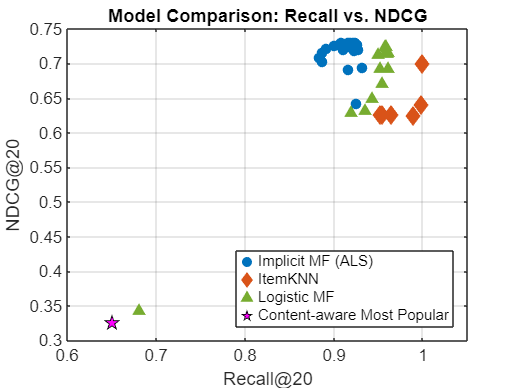

% ================================
% Prepare data from your logs
% ================================

% Implicit MF runs (Recall, NDCG)
mf_recall = [0.9088,0.9073,0.9316,0.8836,0.9254,0.9121,0.9105,0.9160,0.9088,...
             0.9164,0.8917,0.9153,0.9161,0.9187,0.9221,0.9243,0.9235,0.9005,...
             0.9243,0.8867,0.9253,0.9235,0.8867,0.9231,0.9258,0.9260,0.9241,...
             0.9271,0.9211,0.9254];
mf_ndcg   = [0.7301,0.7292,0.6939,0.7086,0.6428,0.7287,0.7202,0.6906,0.7254,...
             0.7250,0.7221,0.7292,0.7300,0.7302,0.7298,0.7263,0.7296,0.7261,...
             0.7296,0.7026,0.7276,0.7187,0.7161,0.7287,0.7251,0.7278,0.7280,...
             0.7201,0.7236,0.7279];

% ItemKNN (best per K)
knn_recall = [0.999872, 0.998969, 0.990023, 0.965213, 0.955082, 0.952560];
knn_ndcg   = [0.699956, 0.640619, 0.624088, 0.626140, 0.626454, 0.626704];

% Logistic MF (only meaningful runs: high recall)
logmf_recall = [0.935776, 0.920210, 0.960518, 0.680779, 0.961200, 0.943819, ...
                0.954929, 0.958073, 0.950592, 0.958959, 0.961362, 0.958959, ...
                0.959070, 0.958499, 0.952876];
logmf_ndcg   = [0.632510, 0.629774, 0.714899, 0.343621, 0.692077, 0.649537, ...
                0.670684, 0.722955, 0.712542, 0.724203, 0.715641, 0.717856, ...
                0.723734, 0.724399, 0.692835];

% Baselines

content_pop_recall = 0.650822;
content_pop_ndcg   = 0.325200;

% ================================
% Plot
% ================================

figure; hold on; grid on; box on;

% Implicit MF
scatter(mf_recall, mf_ndcg, 40, 'filled', 'MarkerFaceColor',[0 0.447 0.741]);
% ItemKNN
scatter(knn_recall, knn_ndcg, 60, 'd', 'MarkerEdgeColor',[0.85 0.325 0.098], ...
    'MarkerFaceColor',[0.85 0.325 0.098]);
% Logistic MF
scatter(logmf_recall, logmf_ndcg, 40, '^', 'MarkerEdgeColor',[0.466 0.674 0.188], ...
    'MarkerFaceColor',[0.466 0.674 0.188]);
% Baselines
scatter(content_pop_recall, content_pop_ndcg, 80, 'p', 'MarkerEdgeColor','k', ...
    'MarkerFaceColor','m');

xlabel('Recall@20');
ylabel('NDCG@20');
title('Model Comparison: Recall vs. NDCG');

legend({'Implicit MF (ALS)','ItemKNN','Logistic MF','Content-aware Most Popular'}, ...
    'Location','southeast');

xlim([0.6 1.05]);
ylim([0.3 0.75]);